## Project Part 2

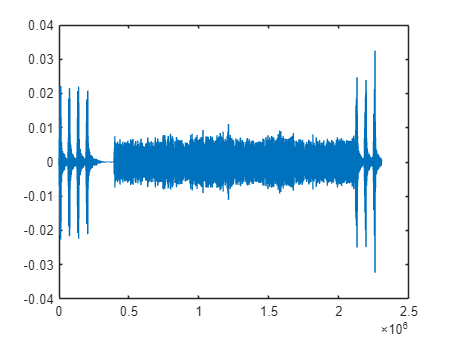

clear all;
K = 2048;
L = 200;
Fc = 24000;
B = 8000;
W = 24;
Lambda = 24;
Sampler = 256000;
vel = 1.03;
c = 1500;
%a = vel/c;
%%% Step 0 Load the .mat files
load("testing_rece_data_171846_1.mat");
y_test1_in = rece_data_ofdm_test;
load("testing_rece_data_171846_2.mat");
y_test2_in = rece_data_ofdm_test;
load("testing_rece_data_171846_3.mat");
y_test3_in = rece_data_ofdm_test;
load("pilot_signal_for_synchronization.mat");
load("ofdm_map.mat");
load("benchmark_parameter_174623_1472.mat");
load("benchmark_rece_data_172648_1.mat");
y_bench1_in = rece_data_ofdm_bench;
load("benchmark_rece_data_172648_2.mat");
y_bench2_in = rece_data_ofdm_bench;
load("benchmark_rece_data_172648_3.mat");
y_bench3_in = rece_data_ofdm_bench;
load("benchmark_Zw_174623_1472.mat");
load("itc_1007_compfilter.mat");
%%% Step 1: PB filter to remove noise beyond PB

%ypb = zeros(length(y_in), 1);
y_bench1_pb = bandpass(y_bench1_in, [-4000+Fc, 4000+Fc], Sampler);
plot(y_bench1_pb);


%%% Step 2: Estimate a
T_tx = 8269.52; %In ms
T_txs = T_tx / 1000; %In sec
sr = 1 / Sampler; %Sampling rate in seconds
T_rx_est = 2115617  * sr; %Estimated Trx duration in sec 2117460 2115617 
a_est = (T_txs/T_rx_est)-1 % The minus 1 was missing before

a_est = 6.5235e-04

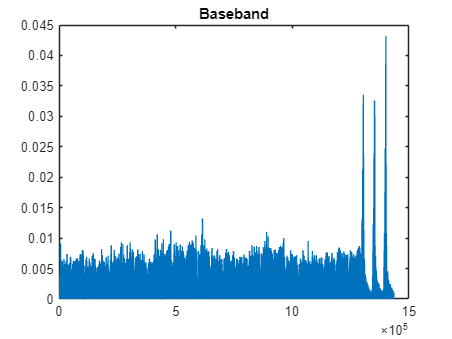

a_est = 3e-4; %TA's given a_hat value, load benchmark_parameter_174623_1472.mat

%%% Step 3: Resampling
%y_pb_re = resample(y_pb, round((1+a)*1*exp(5)), round(1*exp(5))); %%% Double check with TA
y_pb_re = resample(y_bench1_pb, round((1+a_est)*1e5), 1e5);

%%% Step 4: Resampling from 256k to 192k
Ls = 192;
Ms = 256;
Lp = 24;
N = Lp*Ls-1;
h = Ls*fir1(N, 1/Ms, kaiser(N+1, 7.8562));
Ytilda_pb_re = upfirdn(y_pb_re, h, Ls, Ms);
%plot(Ytilda_pb_re);
%freqz(Ytilda_pb_re, 1);

%%% Step 5: Synchronization
pilot = OFDM_data_pre_old; %load pilot_signal_for_syncronizaation.mat
%plot(pilot);

correlate = xcorr(Ytilda_pb_re, pilot); % Correlation with pilot signal
%plot(correlate);

i = max(correlate); % Finds max value index for n_0
for j = 1:length(correlate)
    if i == correlate(j)
        n_0 = j - length(Ytilda_pb_re);
    end
end

Ytilda_n0 = Ytilda_pb_re(n_0:end);    % Truncates signal to start at n_0
%plot(Ytilda_n0)

%%% Step 6 Convolution for PB -> BB
Ytilda_conv = conv(Ytilda_n0, h_comp); % Convolution with 101 sample vector
%plot(Ytilda_conv)
Ytilda_no_delay = Ytilda_conv(51:end); % Cut out first 50 data points of delay

%%% Step 7 PB -> BB
Sampler = 192000;
Y_BB_I = zeros(1, length(Ytilda_no_delay)); % Preallocate arrays for processing speed
Y_BB_Q = zeros(1, length(Ytilda_no_delay));
Y_BB = zeros(1, length(Ytilda_no_delay));
for n = 1:length(Ytilda_no_delay)   % As seen in handout
Y_BB_I(n) = Ytilda_no_delay(n)*2*cos(2*pi*Fc*n*1/Sampler);
Y_BB_Q(n) = -Ytilda_no_delay(n)*2*sin(2*pi*Fc*n*1/Sampler);
Y_BB(n) = Y_BB_I(n) + 1i*Y_BB_Q(n);
end
%plot(Y_BB)

%%% Step 8 Raised Cosine Convolution
beta = .125; % roll-off factor
Fs = 192000; % sampling frequency
Fd = 8000; % data/transfer rate
lamda_oversamp = Fs/Fd; % lambda = 24 defined above works too
delay = 100;    % Given delay in part 1 before oversampling
span = 2*delay;
Rn = rcosdesign(beta, span, Fs/Fd, 'sqrt'); % rcosine filter (similar to sinc function)
%plot(Rn)
plot(abs(Y_BB));    % Checking signal before filtering
title("Baseband");

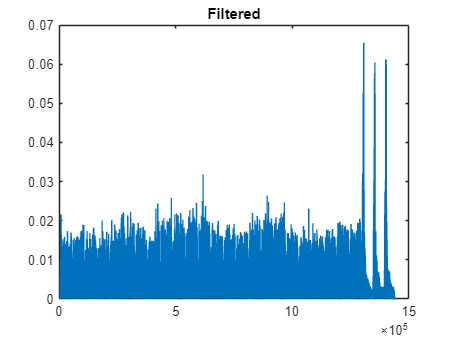

Y_BB_filtered = conv(Y_BB, Rn); % Same as part 1 Step 5
plot(abs(Y_BB_filtered))    % Checking signal after filtering
title("Filtered");

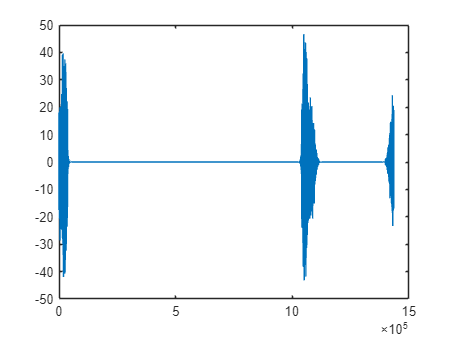

plot(real(fft(Y_BB)))

delay_os = length(Y_BB_filtered)-length(Y_BB)   % Delay obtained by difference of signal lengths 

delay_os = 4800

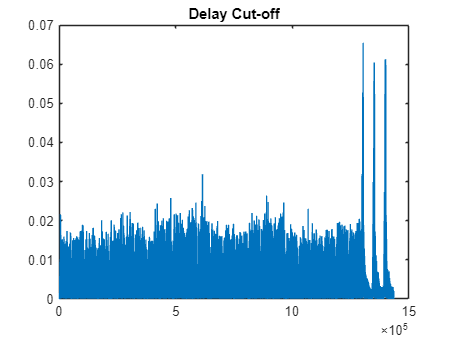

Y_BB_no_delay = Y_BB_filtered(delay_os/2+1:length(Y_BB_filtered)-delay_os/2);   % Cuts out delay
plot(abs(Y_BB_no_delay));   % Should be the same length as Y_BB
title("Delay Cut-off");



%%% Step 9 Grid Search
Ts = 1/Fs;
zp_up = (K+L)*Lambda; %For loop sizes (no minus 1 because 1-indexing)
zp_down = K+L;

% Preallocation of matrices and counters
Y_BB_down = zeros(zp_down, 1);
Z_1 = zeros(zp_down,1);
i = 1:zp_down;
m = (1:2248);
m = transpose(m);
count = 1;
P_NULL = zeros(8241, 1);    % length n_0 x epsilon, 201x41
fft_matrix = exp((-1i*2*pi*(m-1)*(i-1))/K); % FFT
z_count = 1;

    % Null Carriers Step
ofdm = transpose(ofdm_map)

ofdm =      1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2     2     2     1     2


min_OFDM = zeros(zp_down, 1);
for k = 1:K
    if ofdm_map(k, 1) == 0
        min_OFDM(k, 1) = 1;
    end
end

    % Obtain First OFDM Data
for n_0_1 = 2200:1:2400  % n_0,1
    for epsilon_1 = -2:0.1:2 
        n_idx=n_0_1+(0:Lambda:zp_down*Lambda-1);   % CFO Compensation with downsampling
        Y_BB_down(:, 1) = Y_BB_no_delay(n_idx).*exp(-1i*2*pi*epsilon_1*n_idx*Ts);
        Z_1 =  fft_matrix*Y_BB_down;
        %Z_1 = Z_1(1:K, 1);
        P_NULL(count, 1) = sum(Z_1.*conj(Z_1).*min_OFDM);
        count = count + 1;
    end
end
P_NULL_min = min(P_NULL);
P_NULL = reshape(P_NULL, 41, 201);
for o = 1:201
    for p = 1:41
        if P_NULL(p, o) == P_NULL_min
            %o_idx = o
            %p_idx = p
            n_0_1 = o+2199;
            epsilon_1 = p*.1-2.1;
            break
        end
    end
end

% P_null_min = min(P_null);
% for o = 1:length(P_null)
%     if P_null(o, 1) == P_null_min
%         idx_t = o;
%         n_0_1_t = round(idx_t/40+2199);
%         epsilon_1_t = mod(idx_t+40, 40)*.1-2.1;
%     end
% end

Z_1 = Z_1(round(n_0_1/Lambda):end, 1); % Obtain frequency domain data here

Z_all = zeros(zp_down, W-3);
Z_all(1:length(Z_1), 1) = Z_1(1:length(Z_1), 1);

n_all = zeros(W-3, 1);
epsilon_all = zeros(W-3, 1);

n_all(1, 1) = n_0_1;
epsilon_all(1, 1) = epsilon_1;

%%% Step 10
n_0_w_1 = n_0_1;
Z_w = zeros(zp_down,1);

for w = 1:20
    P_NULL = zeros(3977, 1);    % length n_0 x epsilon, 97x41
    count = 1;
    z_count = z_count+1;
    for n_0_w = n_0_w_1 + zp_up + (-2*Lambda:1:2*Lambda)  % Grid Search foor loop
        % n_count = n_count + 1;
        for epsilon_w = -2:0.1:2
            n_idx=n_0_w+ (1:Lambda:zp_down*Lambda);   % CFO Compensation with downsampling
            Y_BB_down(:, 1) = Y_BB_no_delay(n_idx).*exp(-1i*2*pi*epsilon_w*n_idx*Ts);
            Z_w =  fft_matrix*Y_BB_down;
            %Z_w = Z_w(1:K, 1);
            P_NULL(count, 1) = sum(Z_w.*conj(Z_w).*min_OFDM);
            count = count + 1;
        end
    end
    P_NULL_min = min(P_NULL);   % Min P_null
    P_NULL = reshape(P_NULL, 41, 97);
    for o = 1:97
        for p = 1:41
            if P_NULL(p, o) == P_NULL_min
                o_idx = o;
                p_idx = p;
                n_0_w = n_0_w_1+zp_up+o-2*Lambda-1;
                epsilon_w = p*.1-2.1;
                break
            end
        end
    end
    %Z_w = Z_w(round(n_0_w/Lambda):end, 1); % Obtain frequency domain data here
    Z_all(1:end, z_count) = Z_w(1:end, 1);
    n_all(z_count, 1) = n_0_w;
    epsilon_all(z_count, 1) = epsilon_w;
    n_0_w_1 = n_0_w;
end


## Project Part 3

load("OFDM_PILOT.mat"); % Load all necessary Matlab files
load("CODE.mat");
load("INTRLVR.mat");
load("MESG.mat");
load("ofdm_map.mat");
load("benchmark_Zw_172648_1.mat");% First Hydrophone Signal
load("benchmark_Zw_172648_2.mat"); % Second Hydrophone Signal
load("benchmark_Zw_172648_3.mat"); % Third Hydrophone Signal

K = 2048;  % # of subcarriers
L = 199;   % # of taps - 1 for L1 = 0
KN = 112;   % # of null subcarriers
KP = 512;   % # of pilot subcarriers
Kd = 1420;  % # of data subcarriers
W = 21;    % # of OFDM symbols
%z1 = bb_rece_data_172648_1474; % First Hydrophone Signal
z1 = Z_all;
z2 = bb_rece_data_172648_1475; % Second Hydrophone Signal
z3 = bb_rece_data_172648_1476; % Third Hydrophone Signal
%z1 = Z_all;
%zw = Z_w(1:2048, 1);
dp = zeros(KP, 1); % pilot data
pilotind = zeros(KP, 1); % Index of pilot subcarriers
zp1 = zeros(KP, W); % pilot signal 1
zp2 = zeros(KP, W); % pilot signal 2
zp3 = zeros(KP, W); % pilot signal 3
zk1 = zeros(Kd, W); % Data signal 1
zk2 = zeros(Kd, W); % Data signal 2
zk3 = zeros(Kd, W); % Data signal 3
ncount = 1; % Counters
pcount = 1;
dcount = 1;
Hk1 = zeros(Kd, W); % Data only channel 1
Hk2 = zeros(Kd, W); % Data only channel 1
Hk3 = zeros(Kd, W); % Data only channel 1
zn1 = zeros(KN, W); % Null signal 1
zn2 = zeros(KN, W); % Null signal 2
zn3 = zeros(KN, W); % Null signal 3
Hw1 = zeros(K, W); % Whole signal channel 1
Hw2 = zeros(K, W); % Whole signal channel 2
Hw3 = zeros(K, W); % Whole signal channel 3

% Collect pilot and null subcarriers/indices
for k = 1:length(ofdm_map)% Null Index 
    if ofdm_map(k, 1) == 0
        zn1(ncount, :) = z1(k, 1:W);
        zn2(ncount, :) = z2(k, 1:W);
        zn3(ncount, :) = z3(k, 1:W);
        ncount = ncount + 1;
    elseif ofdm_map(k, 1) == 1 % Pilot Index 
        zp1(pcount, :) = z1(k, 1:W);
        zp2(pcount, :) = z2(k, 1:W);
        zp3(pcount, :) = z3(k, 1:W);
        dp(pcount, 1) = OFDM_PILOT(k, 1);
        pilotind(pcount, 1) = k;
        pcount = pcount + 1;
    end 
end

Ds = diag(dp); % Diagonalize pilot data
hls1 = zeros(L+1, W); % Time domain channel 1
hls2 = zeros(L+1, W); % Time domain channel 2
hls3 = zeros(L+1, W); % Time domain channel 3
l = 0:L;
V = exp(-1j*2*pi*(pilotind*l)/K); % estimating time channel
kv = transpose(0:K-1);
Vw = exp(-1j*2*pi*(kv*l)/K); % time to frequency matrix

for w = 1:W % Create Frequency ch
    % +annel from time channel 
    hls1(:, w) = (1/KP)*V'*Ds'*zp1(:, w);
    hls2(:, w) = (1/KP)*V'*Ds'*zp2(:, w);
    hls3(:, w) = (1/KP)*V'*Ds'*zp3(:, w);
    Hw1(:, w) = Vw*hls1(:, w);
    Hw2(:, w) = Vw*hls2(:, w);
    Hw3(:, w) = Vw*hls3(:, w);
end

for k = 1:1:length(ofdm_map) % Get data subcarriers/indices
    if ofdm_map(k, 1) == 2
        zk1(dcount, :) = z1(k, 1:W);
        zk2(dcount, :) = z2(k, 1:W);
        zk3(dcount, :) = z3(k, 1:W);
        Hk1(dcount, :) = Hw1(k, :);
        Hk2(dcount, :) = Hw2(k, :);
        Hk3(dcount, :) = Hw3(k, :);
        dcount = dcount + 1;
    end
end

Task 1b

twosigsquare1 = 1/KN * sum(abs(zn1).^2); % Noise Varience Estimation 1

x1 = 1/sqrt(2)+1i*1/sqrt(2);% QPSK Symbols
x2 = -1/sqrt(2)+1i*1/sqrt(2);
x3 = 1/sqrt(2)-1i*1/sqrt(2);
x4 = -1/sqrt(2)-1i*1/sqrt(2);

    normA = sqrt(conj(zk1 - Hk1*x1).*(zk1 - Hk1*x1));% LLR1 = log((A+C)/(B+D))
    normB = sqrt(conj(zk1 - Hk1*x2).*(zk1 - Hk1*x2));% LLR2 = log((A+B)/(C+D))
    normC = sqrt(conj(zk1 - Hk1*x3).*(zk1 - Hk1*x3));% Lines 101 - 117 accomplish this
    normD = sqrt(conj(zk1 - Hk1*x4).*(zk1 - Hk1*x4));
   
    A = -normA.^2 ./ twosigsquare1;
    B = -normB.^2 ./ twosigsquare1;
    C = -normC.^2 ./ twosigsquare1;
    D = -normD.^2 ./ twosigsquare1;

Lb1_zk = (max(A, C) + log(1+exp(-abs(C-A)))) - (max(B, D) + log(1+exp(-abs(D-B))));
Lb2_zk = (max(A, B) + log(1+exp(-abs(B-A)))) - (max(C, D) + log(1+exp(-abs(D-C))));

LR = zeros(W, 2*Kd); %  Combing both bits post LLR
for w = 1:W
    for n = 1:1:length(Lb1_zk)
        LR(w, 2*n-1) = Lb1_zk(n, w);
        LR(w, 2*n) = Lb2_zk(n, w);
    end
end

Task 1c

Name = './5G_LDPC_M10_N20_Z142_Q2_nonVer.txt'; % One tap equalizer
LPDC_Decoder = open('5G_LDPC_M10_N20_Z142_Q2_nonVer.txt');
[address, LPDC_INFOLEN] = ldpc_mex_initial_CAPI([1420, 2840, 2], Name);

./5G_LDPC_M10_N20_Z142_Q2_nonVer.txt
9 1 259 1 346 1 452 1 899 1 1341 1 1420 1 1562 1 2840 2840 
10 1 260 1 347 1 453 1 900 1 1342 1 1421 1 1563 1 2840 2840 
11 1 261 1 348 1 454 1 901 1 1343 1 1422 1 1564 1 2840 2840 
12 1 262 1 349 1 455 1 902 1 1344 1 1423 1 1565 1 2840 2840 
13 1 263 1 350 1 456 1 903 1 1345 1 1424 1 1566 1 2840 2840 
14 1 264 1 351 1 457 1 904 1 1346 1 1425 1 1567 1 2840 2840 
15 1 265 1 352 1 458 1 905 1 1347 1 1426 1 1568 1 2840 2840 
16 1 266 1 353 1 459 1 906 1 1348 1 1427 1 1569 1 2840 2840 
17 1 267 1 354 1 460 1 907 1 1349 1 1428 1 1570 1 2840 2840 
18 1 268 1 355 1 461 1 908 1 1350 1 1429 1 1571 1 2840 2840 
19 1 269 1 356 1 462 1 909 1 1351 1 1430 1 1572 1 2840 2840 
20 1 270 1 357 1 463 1 910 1 1352 1 1431 1 1573 1 2840 2840 
21 1 271 1 358 1 464 1 911 1 1353 1 1432 1 1574 1 2840 2840 
22 1 272 1 359 1 465 1 912 1 1354 1 1433 1 1575 1 2840 2840 
23 1 273 1 360 1 466 1 913 1 1355 1 1434 1 1576 1 2840 2840 
24 1 274 1 361 1 467 1 914 1 1356 1 1435 1 1577 1

est_code = zeros(length(LR), W);
LR_in_de = zeros(length(LR), W);
APP_code = zeros(length(LR), W);

ber = zeros (1, W);
bec = zeros (1, W);
bler = 0;
for w = 1:W
    LR_in_de(INTRLVR, w) = LR(w, :);
    APP_code(:, w) = ldpcDecoder_CAPI(address, LR_in_de(:, w));
    est_code(:, w) = (APP_code(:, w) < 0);
    bec(1, w) = sum(abs(est_code(:, w) - CODE(:, w)));
    ber(1, w) = bec(1, w) / length(CODE);
    if ber(1, w) ~= 0 && w>1 
        bler = bler + 1;
    end
end
bec_bench1 = sum(bec(1, 2:end))

bec_bench1 = 14199

ber_bench1 = sum(ber(1, 2:end))/(W-1)

ber_bench1 = 0.2500

bler_bench1 = bler/(W-1)

bler_bench1 = 1

Task 2

% %%% 2 Hydrophones %%%
% 
% twosigsquare2 = 1/KN * sum(abs(zn2).^2); % Noise Varience Estimation 2
% normHk2 = zeros(Kd, W);
% for w = 1:W
%     for kd = 1:Kd
%         normHk2(kd, w) = sqrt(Hk1(kd, w)'*Hk1(kd, w) + Hk2(kd, w)'*Hk2(kd, w));
%     end
% end
% hermHk1 = Hk1';
% hermHk2 = Hk2';
% qk2 = zeros(Kd, W);
% for w = 1:W
%     for kd = 1:Kd
%         qk2(kd, w) = [hermHk1(w, kd), hermHk2(w, kd)]*[zk1(kd, w); zk2(kd, w)];
%     end
% end
% qk2 = qk2./normHk2;
% 
% sumSigSquared2 = twosigsquare1.*(conj(Hk1).*Hk1)+twosigsquare2.*(conj(Hk2).*Hk2);
% twosigsquare2comb = 1./(normHk2.^2).*sumSigSquared2;
% 
% absA2 = abs(qk2 - normHk2.*x1).^2;
% absB2 = abs(qk2 - normHk2.*x2).^2;
% absC2 = abs(qk2 - normHk2.*x3).^2;
% absD2 = abs(qk2 - normHk2.*x4).^2;
% 
% A2 = -absA2 ./ twosigsquare2comb;
% B2 = -absB2 ./ twosigsquare2comb;
% C2 = -absC2 ./ twosigsquare2comb;
% D2 = -absD2 ./ twosigsquare2comb;
% 
% Lb1_zk2 = (max(A2, C2) + log(1+exp(-abs(C2-A2)))) - (max(B2, D2) + log(1+exp(-abs(D2-B2))));
% Lb2_zk2 = (max(A2, B2) + log(1+exp(-abs(B2-A2)))) - (max(C2, D2) + log(1+exp(-abs(D2-C2))));
% 
% LR2 = zeros(W, 2*Kd); %  Combing both bits post LLR
% for w = 1:W
%     for n = 1:1:length(Lb1_zk2)
%         LR2(w, 2*n-1) = Lb1_zk2(n, w);
%         LR2(w, 2*n) = Lb2_zk2(n, w);
%     end
% end
% 
% est_code2 = zeros(length(LR2), W);
% LR_in_de2 = zeros(length(LR2), W);
% APP_code2 = zeros(length(LR2), W);
% 
% ber2 = zeros (1, W);
% bec2 = zeros (1, W);
% bler2 = 0;
% for w = 1:W
%     LR_in_de2(INTRLVR, w) = LR2(w, :);
%     APP_code2(:, w) = ldpcDecoder_CAPI(address, LR_in_de2(:, w));
%     est_code2(:, w) = (APP_code2(:, w) < 0);
%     bec2(1, w) = sum(abs(est_code2(:, w) - CODE(:, w)));
%     ber2(1, w) = bec2(1, w) / length(CODE);
%     if ber2(1, w) ~= 0 && w>1 
%         bler2 = bler2 + 1;
%     end
% end
% bec_bench2 = sum(bec2(1, 2:end))
% ber_bench2 = sum(ber2(1, 2:end))/(W-1)
% bler_bench2 = bler2/(W-1)
% 
% %%% 3 Hydrophones %%%
% 
% twosigsquare3 = 1/KN * sum(abs(zn3).^2); % Noise Varience Estimation 3
% normHk3 = zeros(Kd, W);
% for w = 1:W
%     for kd = 1:Kd
%         normHk3(kd, w) = sqrt(Hk1(kd, w)'*Hk1(kd, w)+Hk2(kd, w)'*Hk2(kd, w)+Hk3(kd, w)'*Hk3(kd, w));
%     end
% end
% hermHk3 = Hk3';
% qk3 = zeros(Kd, W);
% for w = 1:W
%     for kd = 1:Kd
%         qk3(kd, w) = [hermHk1(w, kd), hermHk2(w, kd), hermHk3(w, kd)]*[zk1(kd, w); zk2(kd, w); zk3(kd, w)];
%     end
% end
% qk3 = qk3./normHk3;
% 
% sumSigSquared3 = twosigsquare1.*(conj(Hk1).*Hk1)+twosigsquare2.*(conj(Hk2).*Hk2)+twosigsquare3.*(conj(Hk3).*Hk3);
% twosigsquare3comb = 1./(normHk3.^2).*sumSigSquared3;
% 
% absA3 = abs(qk3 - normHk3.*x1).^2;
% absB3 = abs(qk3 - normHk3.*x2).^2;
% absC3 = abs(qk3 - normHk3.*x3).^2;
% absD3 = abs(qk3 - normHk3.*x4).^2;
% 
% A3 = -absA3 ./ twosigsquare3comb;
% B3 = -absB3 ./ twosigsquare3comb;
% C3 = -absC3 ./ twosigsquare3comb;
% D3 = -absD3 ./ twosigsquare3comb;
% 
% Lb1_zk3 = (max(A3, C3) + log(1+exp(-abs(C3-A3)))) - (max(B3, D3) + log(1+exp(-abs(D3-B3))));
% Lb2_zk3 = (max(A3, B3) + log(1+exp(-abs(B3-A3)))) - (max(C3, D3) + log(1+exp(-abs(D3-C3))));
% 
% LR3 = zeros(W, 2*Kd); %  Combing both bits post LLR
% for w = 1:W
%     for n = 1:1:length(Lb1_zk3)
%         LR3(w, 2*n-1) = Lb1_zk3(n, w);
%         LR3(w, 2*n) = Lb2_zk3(n, w);
%     end
% end
% 
% est_code3 = zeros(length(LR2), W);
% LR_in_de3 = zeros(length(LR2), W);
% APP_code3 = zeros(length(LR2), W);
% 
% ber3 = zeros (1, W);
% bec3 = zeros (1, W);
% bler3 = 0;
% for w = 1:W
%     LR_in_de3(INTRLVR, w) = LR3(w, :);
%     APP_code3(:, w) = ldpcDecoder_CAPI(address, LR_in_de3(:, w));
%     est_code3(:, w) = (APP_code3(:, w) < 0);
%     bec3(1, w) = sum(abs(est_code3(:, w) - CODE(:, w)));
%     ber3(1, w) = bec3(1, w) / length(CODE);
%     if ber3(1, w) ~= 0 && w>1 
%         bler3 = bler3 + 1;
%     end
% end
% bec_bench3 = sum(bec3(1, 2:end))
% ber_bench3 = sum(ber3(1, 2:end))/(W-1)
% bler_bench3 = bler3/(W-1)